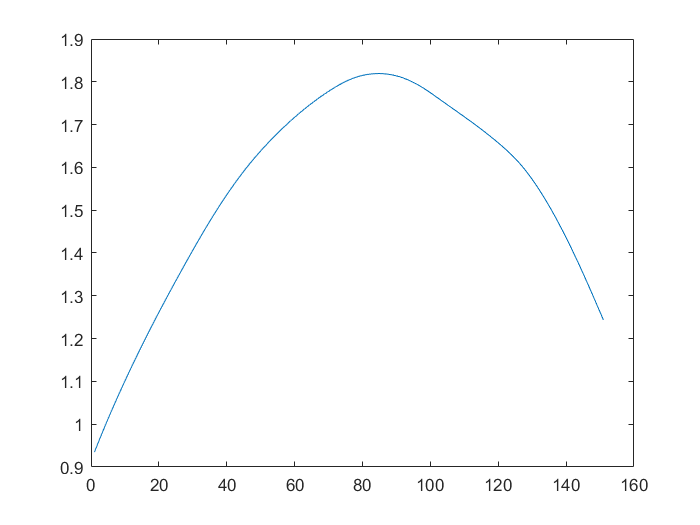

quat_b = SCA1B20030210B03(85021: 5: 85021 + 750, :);
quat_a = SCA1B20030210A03(84526: 5: 84526 + 750, :);

x = [1.4451172588 -0.0004233040 0.0022786600 -1.4443870350 -0.0005761203 -0.0033040887];
% quat_b = SCA1B20030210B02(16916: 16916 + 150, :);
% quat_a = SCA1B20030210A02(16935: 16935 + 150, :);

e = GNV1B20030210A02(17017: 17017 + 150, 1: 3) - GNV1B20030210B02(17017: 17017 + 150, 1: 3);
dis_e = sqrt(diag(e * e'));
eqa = zeros(length(e), 6);

for i = 1: length(e)
    rotm_a = q2m(quat_a(i, :));
    rotm_b = q2m(quat_b(i, :));
    eqa(i, 1: 3) = e(i, :) * rotm_a' / dis_e(i);
    eqa(i, 4: 6) = e(i, :) * rotm_b' / dis_e(i);
end
eqb = kbr_x(16775: 16775 + 150, 1) - dis(17017: 17017 + 150);

plot(eqa * x')